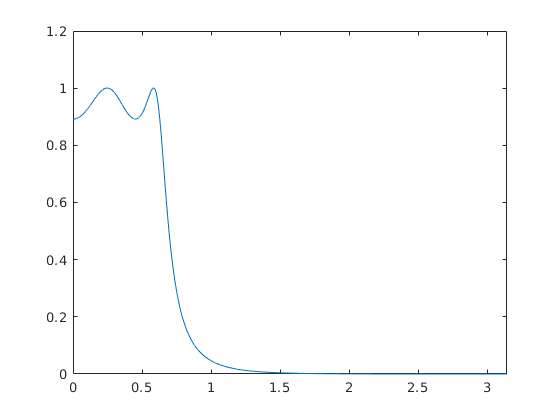

z = tf('z');

%% Passa-Baixa

numd = .001836*(1+z^-1)^4;
dend = (1-1.5548*(z^-1) + .6493*(z^-2))*(1-1.4996*(z^-1) + 0.8482*(z^-2));
H_lp = numd/dend;

[num,den] = tfdata(H_lp,'v');

f = 0:.0001:pi;
[mag, w] = freqz(num,den,f);
plot(f, abs(mag))
ylim([0, 1.2]);
xlim([0, pi]);

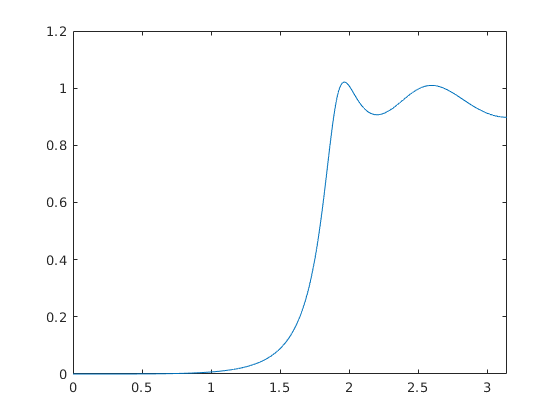


%% Passa-Alta

numd = 0.02426*(1 - z^-1)^4;
dend = (1+1.0416*z^-1 + .4019*z^-2)*(1+.5661*z^-1+.7657*z^-2);
H_z = numd/dend;

[num,den] = tfdata(H_z,'v');

f = 0:.0001:pi;
[mag, w] = freqz(num,den,f);
plot(f, abs(mag))
ylim([0, 1.2]);
xlim([0, pi]);